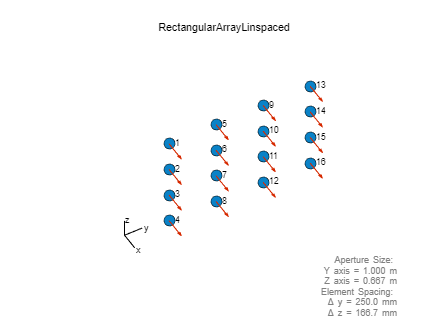


% MATLAB Code from Sensor Array Analyzer App

% Generated by MATLAB 9.11 and Phased Array System Toolbox 4.6

% Generated on 20-Apr-2022 17:27:17

% Create a uniform rectangular array
Array = phased.URA('Size',[4 4],...
'Lattice','Rectangular','ArrayNormal','x');
Array.ElementSpacing = [0.1667 0.25];
% Calculate Row taper
rwind = ones(1,4).';
% Calculate Column taper
cwind = ones(1,4).';
% Calculate taper
taper = rwind*cwind.';
Array.Taper = taper.';

% Create an omnidirectional microphone element
Elem = phased.OmnidirectionalMicrophoneElement;
Elem.FrequencyRange = [20 20e3];
Elem.BackBaffled = false;
Array.Element = Elem;
% Create Figure

[dir, fname,~] = fileparts(matlab.desktop.editor.getActiveFilename);

save(dir + "\Arrays\" + fname + ".mat", "Array")

% % Plot Array Geometry
simulation.viewSensorArray3D(Array, fname)


[b, fname,a] = fileparts(matlab.desktop.editor.getActiveFilename)

b = 'C:\Users\ru121koh\Desktop\PA-akustische-kamera\ArrayDesignStudies'

fname = 'RectangularArrayLinspaced'

a = '.mlx'